swing_init;

obsInfo = rlNumericSpec([1 1],...
    'LowerLimit',-40,...
    'UpperLimit',40);
obsInfo.Name = 'observations';
obsInfo.Description = 'swing position';
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([1 1],...
    'LowerLimit',0,...
    'UpperLimit',30);
actInfo.Name = 'action';
numActions = 1;

env = rlSimulinkEnv('swing_model','swing_model/RL Agent',...
    obsInfo,actInfo);

env.ResetFcn = @(in)localResetFcn(in);

Ts = 0.05;  %world resolution
Tf = 10;    %episode length

rng(0);

statePath = [
    imageInputLayer([numObservations 1 1], 'Normalization', 'none', 'Name', 'State')
    fullyConnectedLayer(400, 'Name', 'CriticStateFC1')
    reluLayer('Name', 'CriticRelu1')
    fullyConnectedLayer(300, 'Name', 'CriticStateFC2')];
actionPath = [
    imageInputLayer([numActions 1 1], 'Normalization', 'none', 'Name', 'Action')
    fullyConnectedLayer(300, 'Name', 'CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name', 'add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1, 'Name', 'CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

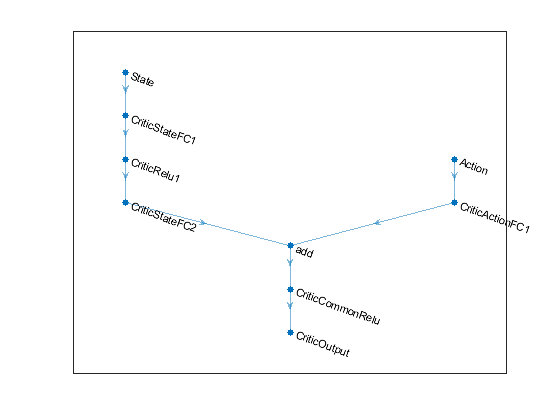

figure
plot(criticNetwork)

criticOpts = rlRepresentationOptions('LearnRate',1e-02,'GradientThreshold',1,'UseDevice',"gpu");

critic = rlRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

actorNetwork = [
    imageInputLayer([numObservations 1 1], 'Normalization', 'none', 'Name', 'State')
    fullyConnectedLayer(400, 'Name', 'actorFC1')
    reluLayer('Name', 'ActorRelu1')
    fullyConnectedLayer(300, 'Name', 'ActorFC2')
    reluLayer('Name', 'ActorRelu2')
    fullyConnectedLayer(1, 'Name', 'ActorFC3')
    tanhLayer('Name', 'actorTanh')
    fullyConnectedLayer(numActions, 'Name', 'Action')
    ];

%actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1,'UseDevice',"gpu");
actorOptions = rlRepresentationOptions('LearnRate',0.9,'GradientThreshold',1,'UseDevice',"gpu");

actor = rlRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

%figure
%plot(actorNetwork)

numGPUs = 1;
miniBatchSize = 64*numGPUs;
agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',0.99, ...
    'MiniBatchSize',miniBatchSize, ...
    'ExperienceBufferLength',1e6); 
agentOpts.NoiseOptions.Variance = 0.3;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;
agentOpts.SaveExperienceBufferWithAgent=1;

agent = rlDDPGAgent(actor,critic,agentOpts);
%error('Script episode reached. Stop.')

%train
maxepisodes = 3;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'UseParallel', false, ...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',20, ...
    'Verbose', false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',1,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',0.1);

doTraining = true;
if doTraining
    trainingStats = train(agent,env,trainOpts);
    save('agent_mind_b.mat','agent');
end

if doTraining==false
    load('agent_mind_b.mat','agent');
end

%validate
simOpts = rlSimulationOptions('MaxSteps',maxsteps,...
    'StopOnError','off');

%experiences = sim(env,agent,simOpts);

function in = localResetFcn(in)

%     joint_start_pos=90+rand*20-10;
%     joint_start_velocity=90+rand*2-1;
%     swing_blk = 'swing_model/swing system/top revolute frame';
%     %get_param('swing_model/swing system/top revolute frame','ObjectParameters')
%     in.setBlockParameter(swing_blk,'PositionTargetValue',0);
%     in.setBlockParameter(swing_blk,'VelocityTargetValue',0); 
%     
%     leg_blk = 'swing_model/leg/leg servo';
%     in.setBlockParameter(leg_blk,'PositionTargetValue',-90);
    
end